m=mobiledev

m = mobiledev with properties:

                      Device: 'Galaxy A52s 5G'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 1
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0
Show all properties

m.AccelerationSensorEnabled = 1;
m.Logging = 1;


m.Logging = 0;
m.AccelerationSensorEnabled = 0;


[a, t] = accellog(m);
%[o, t2]=orientlog(m);

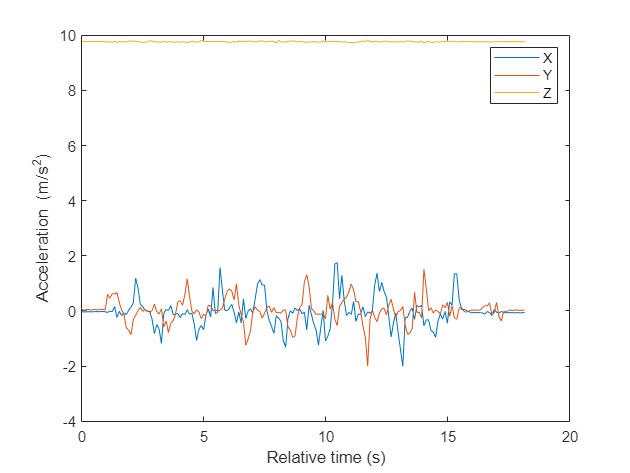


plot(t, a);
legend('X', 'Y', 'Z');
xlabel('Relative time (s)');
ylabel('Acceleration (m/s^2)');

for i= 1:length(t)
    if (abs(a(i,1))<0.2)
        a(i,1)=0;
    end
    if (abs(a(i,2))<0.2) %초기0.1에서 변경
        a(i,2)=0;
    end
end

window = 7;
h = normpdf( -window:window, 0, fix((2*window+1)/6) );
filterAX = filter(h, 1, a(:,1));
filterAY = filter(h, 1, a(:,2));
% plot(916), plot( y ), set(gca, 'YLim', [-1 1], 'xtick',[])
% title('gaussian')

% plot(t2, o);
% legend('X', 'Y', 'Z');
% xlabel('Relative time (s)');
% ylabel('Acceleration (m/s^2)');


% t(end)
% length(t)
% a(1,2)

for i= 1:length(t)
    if i==1        
         vx(i)= 0+a(i,1)*(t(end)/length(t));
         vy(i)= 0+a(i,2)*(t(end)/length(t));
    else
        vx(i)= vx(i-1)+a(i,1)*(t(end)/length(t));
        vy(i)= vy(i-1)+a(i,2)*(t(end)/length(t));
    end
end
for i= 1:length(t)
    if (vx(i)<0.01)
        vx(i)=0;
    elseif(vy(i)<0.01)
        vy(i)=0;
    end
end

plot(t, vx);hold

현재 플롯이 유지됨


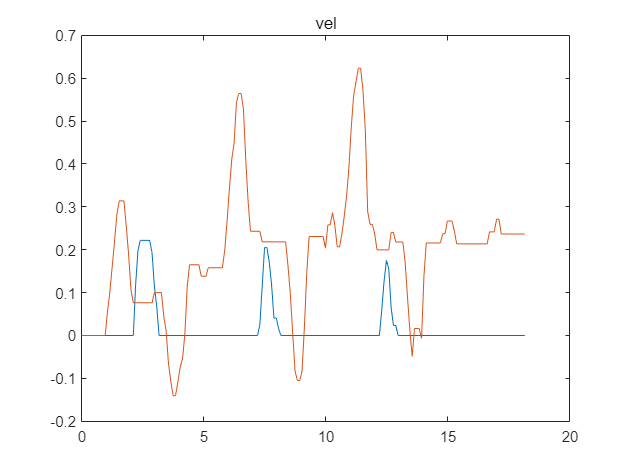

plot(t, vy);hold off
title('vel')


for i= 1:length(t)
    if i==1
        filtervx(i)= 0+filterAX(i)*(t(end)/length(t));
        filtervy(i)= 0+filterAY(i)*(t(end)/length(t));
    else
        filtervx(i)= filtervx(i-1)+filterAX(i)*(t(end)/length(t));
        filtervy(i)= filtervy(i-1)+filterAY(i)*(t(end)/length(t));
    end
end

for i= 1:length(t)
    if (filtervx(i)<0.01)
        filtervx(i)=0;
    elseif(filtervy(i)<0.01)
        filtervy(i)=0;
    end
end

plot(t, filtervx);hold

현재 플롯이 유지됨


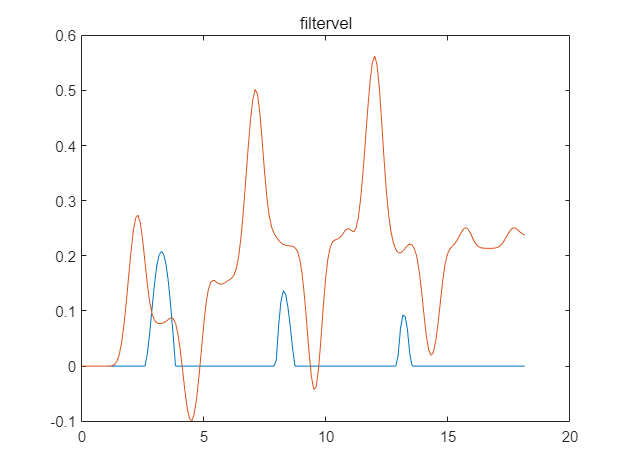

plot(t, filtervy);hold off
title('filtervel')

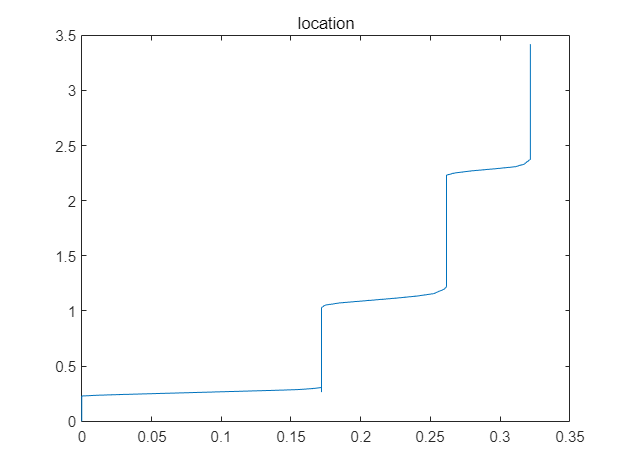


for i= 1:length(t)
    if i==1
        px(i)= 0+vx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        py(i)= 0+vy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    else
        px(i)= px(i-1)+vx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        py(i)= py(i-1)+vy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    end

end
plot(px,py)
title("location")

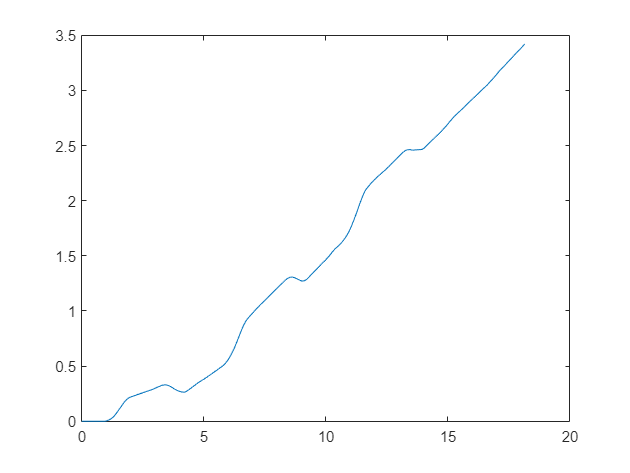

plot(t,py)

lotation=[px ; py]

lotation =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0114    0.0304    0.0516    0.0727    0.0939    0.1151    0.1362    0.1546    0.1655    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719
         0         0         0         0         0         0         0         0         0         0         0    0.0055    0.0151    0.0305    0.0515    0.0786    0.1086    0.1385    0.1685    0.1928    0.2108    0.2209    0.2282    0.2355    0.2428    0.2500    0.2573    0.2646    0.2719    0.2791    0.2864    0.2959    0.3055    0.3150    0.3245    0.3288    0.3298    0.3235    0.3133    0.2999    0.2864    0.2760    0.2690    0.2638    0.2640    0.2750    0.2907    0.3065    0.32

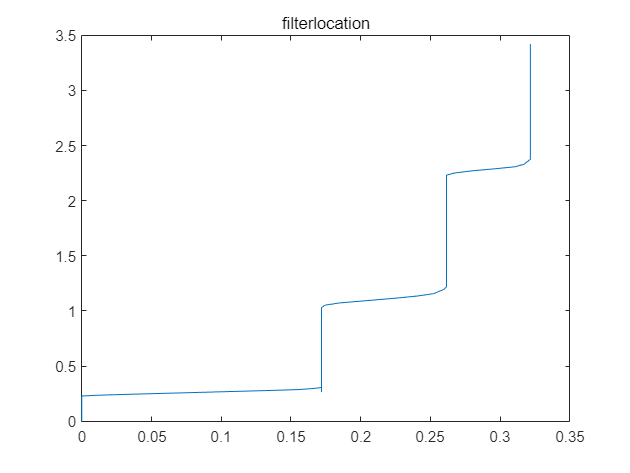


for i= 1:length(t)
    if i==1
        filterpx(i)= 0+filtervx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        filterpy(i)= 0+filtervy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    else
        filterpx(i)= filterpx(i-1)+vx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        filterpy(i)= filterpy(i-1)+vy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    end
end
plot(filterpx,filterpy)
title("filterlocation")

plot(t,filterpy)

filterlotation=[filterpx;filterpy]

filterlotation =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0114    0.0304    0.0516    0.0727    0.0939    0.1151    0.1362    0.1546    0.1655    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719    0.1719
         0         0         0         0         0         0         0         0         0         0         0    0.0055    0.0151    0.0305    0.0515    0.0786    0.1086    0.1385    0.1685    0.1928    0.2108    0.2209    0.2282    0.2355    0.2428    0.2500    0.2573    0.2646    0.2719    0.2791    0.2864    0.2959    0.3055    0.3150    0.3245    0.3288    0.3298    0.3235    0.3133    0.2999    0.2864    0.2760    0.2690    0.2638    0.2640    0.2750    0.2907    0.3065  

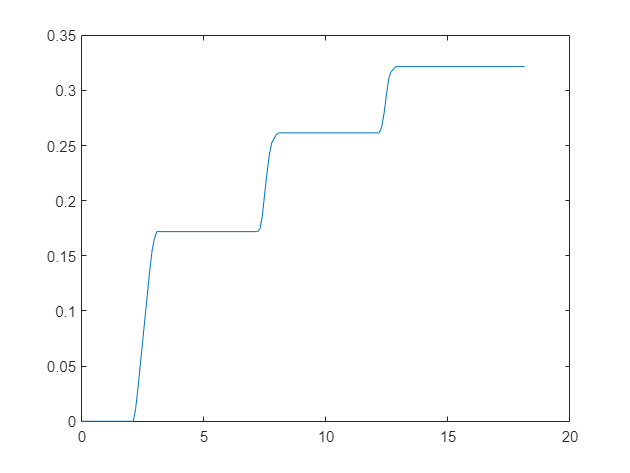

plot(t,px)

plot(t,filterpx)

%m.AccelerationSensorEnabled = 0;

clear m;




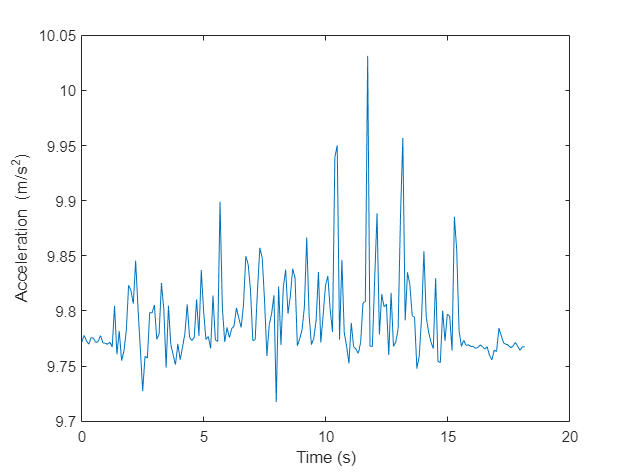

x = a(:,1);
y = a(:,2);
z = a(:,3);

% Calculate and plot magnitude.
mag = sqrt(sum(x.^2 + y.^2 + z.^2, 2));
plot(t, mag);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

m.Acceleration(1)

이름 'm.Acceleration'을(를) 확인할 수 없습니다.

 
velocity.X = cumtrapz(1/10,acceleration.X/1000*9.81);
volocity.Y = cumtrapz(1/10,acceleration.Y/1000*9.81);
velocity.Z = cumtrapz(1/10,acceleration.Z/1000*9.81);
position.X = trapz(1/10,velocity.X);
position.Y = trapz(1/10,velocity.Y);
position.Z = trapz(1/10,velocity.Z);